Initialize the environment

clear all;
close all;

Define the Laplace variable and the system

s = tf('s');
G = 1/(s^2 + 8.8*s + 40);

Root locus with C=1

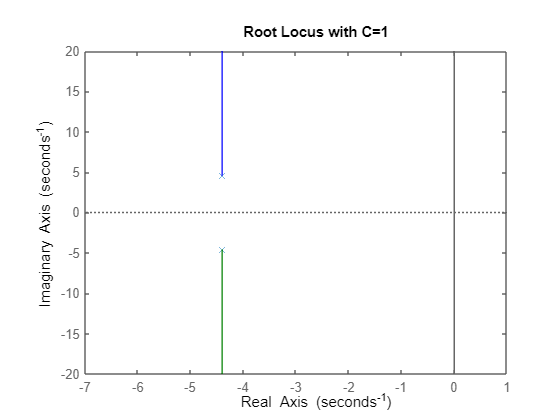

C = 1;
figure;
rlocus(C*G);
title('Root Locus with C=1');

Step response for C=1

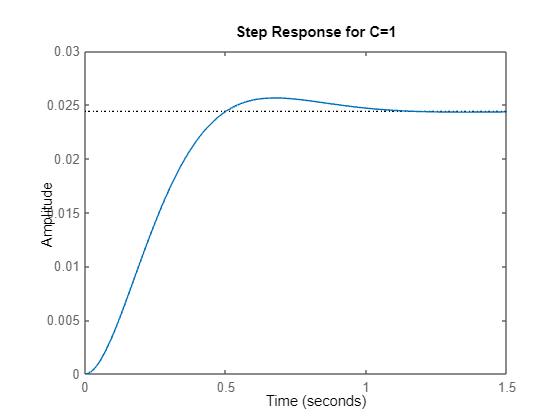

GCL = minreal(feedback(C*G, 1));
figure;
step(GCL);
title('Step Response for C=1');

Increase gain for improved steady state response

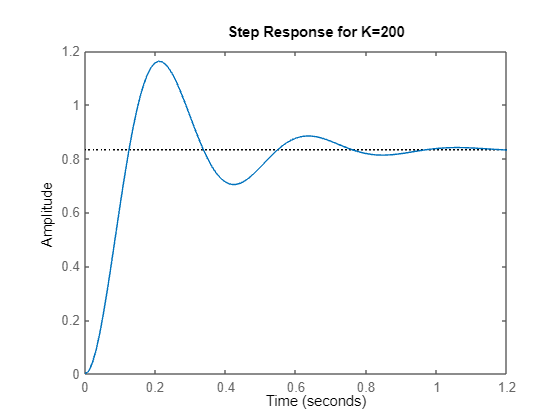

K = 200;
C = K;
GCL = minreal(feedback(C*G, 1));
figure;
step(GCL);
title('Step Response for K=200');

Root locus with an integrator

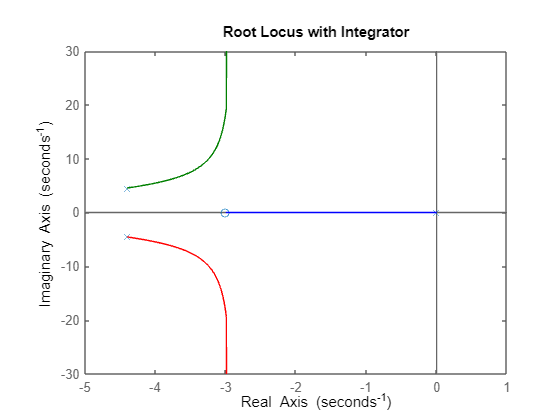

kp = 1;
ki = 3;
C = kp + ki/s;
figure;
rlocus(C*G);
title('Root Locus with Integrator');

Step response with K=50 and an integrator

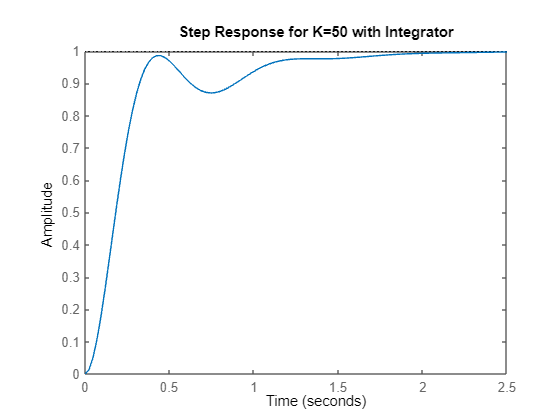

K = 50;
C = K*(kp + ki/s);
GCL = minreal(feedback(C*G, 1));
figure;
step(GCL);
title('Step Response for K=50 with Integrator');